% 加载图像数据集
trainFolder = 'C:\Users\Windows 10\Desktop\train';
valFolder = 'C:\Users\Windows 10\Desktop\val';


trainDatastore = imageDatastore(trainFolder, ...
    'IncludeSubfolders', true, 'LabelSource', 'foldernames');
valDatastore = imageDatastore(valFolder, ...
    'IncludeSubfolders', true, 'LabelSource', 'foldernames');


inputSize = [224, 224]; 
trainDatastore.ReadFcn = @(filename)imresize(rgb2gray(imread(filename)), inputSize);
valDatastore.ReadFcn = @(filename)imresize(rgb2gray(imread(filename)), inputSize);


trainData = [];
trainLabels = [];
while hasdata(trainDatastore)
    img = read(trainDatastore);
    img = img(:)'; 
    trainData = [trainData; img];
end
trainLabels = trainDatastore.Labels; 

valData = [];
valLabels = [];
while hasdata(valDatastore)
    img = read(valDatastore);
    img = img(:)'; 
    valData = [valData; img];
end
valLabels = valDatastore.Labels;


fprintf('训练数据大小: %d x %d\n', size(trainData, 1), size(trainData, 2));

训练数据大小: 600 x 50176


fprintf('训练标签大小: %d\n', length(trainLabels));

训练标签大小: 600


fprintf('验证数据大小: %d x %d\n', size(valData, 1), size(valData, 2));

验证数据大小: 300 x 50176


fprintf('验证标签大小: %d\n', length(valLabels));

验证标签大小: 300




[trainLabels, ~] = grp2idx(trainLabels);
[valLabels, ~] = grp2idx(valLabels);


assert(size(trainData, 1) == length(trainLabels), '训练数据和标签数量不一致');
assert(size(valData, 1) == length(valLabels), '验证数据和标签数量不一致');




k = 5;


[rec_rate, pre_label] = basicKNN(trainData, trainLabels, valData, valLabels, k);


fprintf('识别率: %.2f%%\n', rec_rate * 100);

识别率: 41.33%


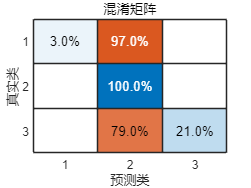


pre_label_cat = categorical(pre_label);


valLabels_cat = categorical(valLabels);


figure;
cm = confusionchart(valLabels_cat, pre_label_cat);

cm.Title = '混淆矩阵';
cm.Normalization = 'row-normalized'; 


cm

cm =   ConfusionMatrixChart (混淆矩阵) - 属性:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 categorical]

  显示 所有属性


function [rec_rate, pre_label] = basicKNN(Traindata, Trainlabel, Testdata, Testlabel, k)
    num_train = size(Traindata, 1);
    num_test = size(Testdata, 1);
    pre_label = zeros(num_test, 1);
    
    for i = 1:num_test
       
        temp = repmat(Testdata(i, :), [num_train, 1]);
        diff = Traindata - temp;
        Euc_dist = sqrt(sum(diff.^2, 2));
        
      
        [~, index] = sort(Euc_dist);
        k_label = Trainlabel(index(1:k));
        
       
        table = tabulate(k_label);
        value = table(:, 1);
        count = table(:, 2);
        [~, ind] = max(count);
        pre_label(i) = value(ind);
    end
    
    Err = sum(pre_label ~= Testlabel);
    rec_rate = 1 - Err / length(Testlabel);
end
